We solve the advection equation on a domain with periodic end conditions. Our approach is the method of lines.

c = 2;
[x,Dx,Dxx] = diffper(300,[-4,4]);
f = @(t,u) -c*(Dx*u);

The following initial condition isn't mathematically periodic, but the deviation is less than machine precision. 

u_init = 1 + exp(-3*x.^2);
t = linspace(0,3,41);
[t,U] = ode45(f,t,u_init);

A nice way to visualize solutions with moving features is by a `waterfall` plot.

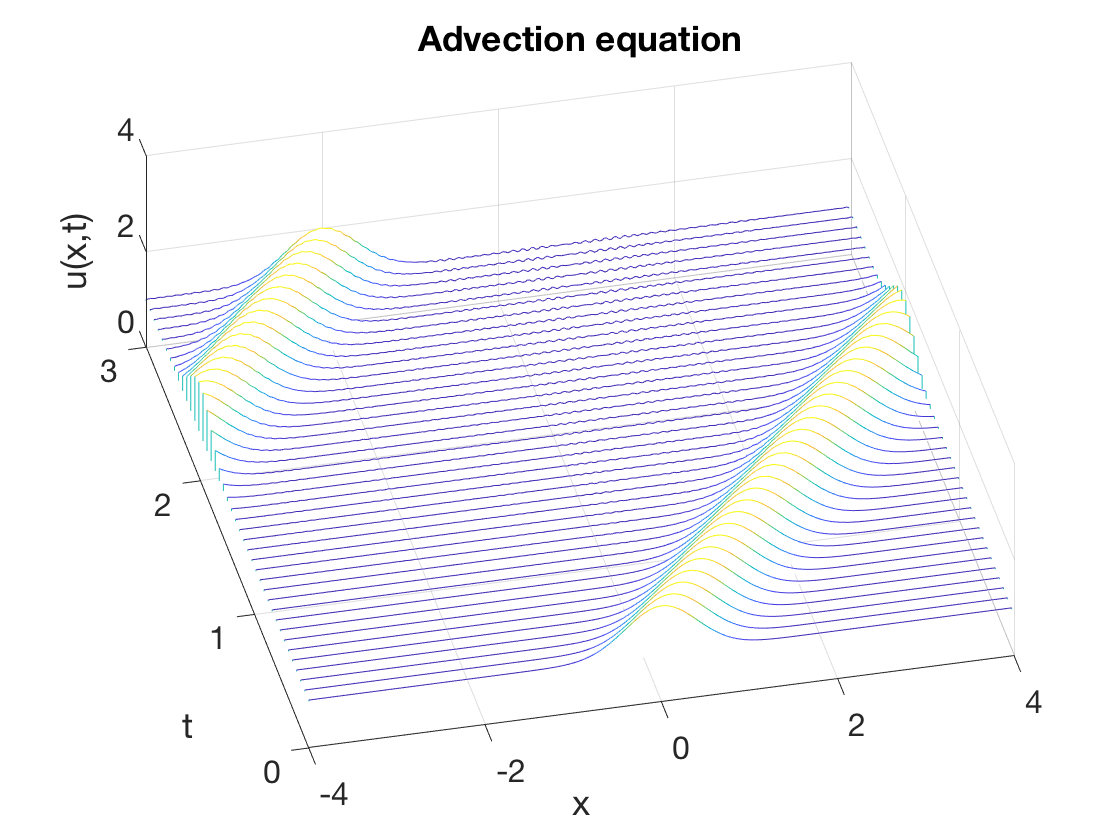

waterfall(x,t,U)
view(-13,65)
xlabel('x'), ylabel('t'), zlabel('u(x,t)')    % ignore this line
title('Advection equation')     % ignore this line

The bump moves with speed 2 to the right, reentering on the left as it exits to the right because of the periodic conditions. 